# Validation on how PCA and Autoencoder works

clc
close all;
clear all;
rng 'default'
uqlab

Copyright 2013-2022, Stefano Marelli and Bruno Sudret, all rights reserved.
This is UQLab, version 2.0
UQLab is distributed under the BSD 3-clause open source license available at: 
C:\Users\ny123\OneDrive - Imperial College London\PhD_Work\UQlab\UQLab_Rel2.0.0\UQLab_Rel2.0.0\LICENSE.

To request special permissions, please contact:
  - Stefano Marelli (<a href="mailto:marelli@ibk.baug.ethz.ch">marelli@ibk.baug.ethz.ch</a>).

Useful commands to get started with UQLab:
uqlab -doc           - Access the available documentation
uqlab -help          - Additional help on how to get started with UQLab
uq_citation help   - Information on how to cite UQLab in publications
uqlab -license       - Display UQLab license information



## Generate data

%generate fake Gaussian data
    % M = 50; % Number of observations
    % N = 100; % Number of variables 
    % 
    % 
    % R = randn(N,N); %generate roration matrix
    % T = randn(M,N)+32; %generate the tranlation displacement
    % 
    % Y_GT = randn(M,N)*R+T;%generate raw data

% mu = [30 -10 0.3 25 36 35 32 65 62 10];
% Sigma = [1 0.9 0.8 0.7 0.6 0.5 0.4 0.3 0.2 0.1;
%          0.9 1 0.9 0.8 0.7 0.6 0.5 0.4 0.3 0.2;
%          0.8 0.9 1 0.9 0.8 0.7 0.6 0.5 0.4 0.3;
%          0.7 0.8 0.9 1 0.9 0.8 0.7 0.6 0.5 0.4;
%          0.6 0.7 0.8 0.9 1 0.9 0.8 0.7 0.6 0.5;
%          0.5 0.6 0.7 0.8 0.9 1 0.9 0.8 0.7 0.6;
%          0.4 0.5 0.6 0.7 0.8 0.9 1 0.9 0.8 0.7;
%          0.3 0.4 0.5 0.6 0.7 0.8 0.9 1 0.9 0.8;
%          0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1 0.9;
%          0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1];
% 
% 
% Y_GT = mvnrnd(mu,Sigma,1000);


load data


%load FE deflection 
    %Y_GT = readmatrix('FE_abaqus_excavation.txt');
    Y_GT = readmatrix('FE_deflection_beam_deflection.txt');
    %Y_GT = readmatrix('FE_Zachary_excavation.txt');
    %Y_GT = readmatrix('FE_deflection_truss');
% size of the FE realization n by p, n Fe realization, p output dimensions
    [n,p] = size(Y_GT);


## PCA (N X P)

%PCA analysis   

   %[Zscore_Y_GT, Zscore_mv, Zscore_std] = zscore(Y_GT);
   [coeff_1,score_1,latent_1,~,explained_1,mu_1] = pca(Y_GT,'Economy',false);

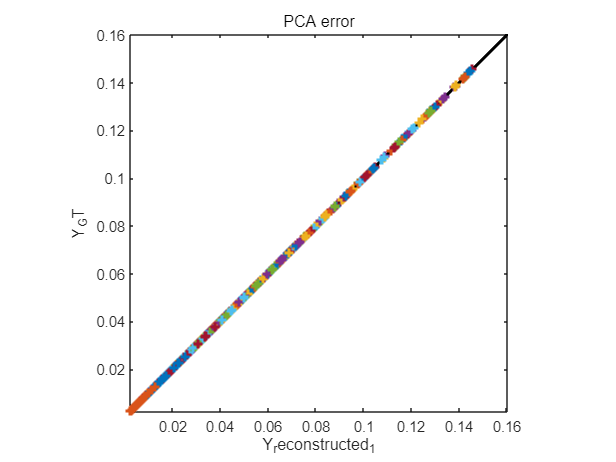



    %Y_validate = Y_GT - mu_1;
    %PC_validate = Y_validate * coeff_1(:,1:2);

    

%select the numbers of  PCs
    N_PC =2;
    PC_1 = score_1(:,1:N_PC);

%reconstruct the data Y_GT as Y_reconstructed_1
    Y_reconstructed_1 = PC_1 * coeff_1(:,1:N_PC)' + repmat(mu_1,n,1);
    % Y_reconstructed_1 = Y_reconstructed_1 .*Zscore_std + Zscore_mv;

%plot the PCA truncation error as Y_reconstructed_1 vs Y_GT
    figure();
    hold on;
    uq_plot([0.9*min(Y_GT,[],'all') 1.1*max(Y_GT,[],'all')], [0.9*min(Y_GT,[],'all') 1.1*max(Y_GT,[],'all')], 'k');
    axis equal;
    axis([[0.9*min(Y_GT,[],'all') 1.1*max(Y_GT,[],'all')], [0.9*min(Y_GT,[],'all') 1.1*max(Y_GT,[],'all')]]);
    uq_plot(Y_GT, Y_reconstructed_1, '+');
    xlabel('Y_reconstructed_1');
    ylabel('Y_GT');
    box on;
    hold off;
    title('PCA error');

PCA MSE percentage error

    mseError_PCA = mse((Y_GT-Y_reconstructed_1)./Y_GT)

mseError_PCA = 7.2875e-25

PCA error covariance

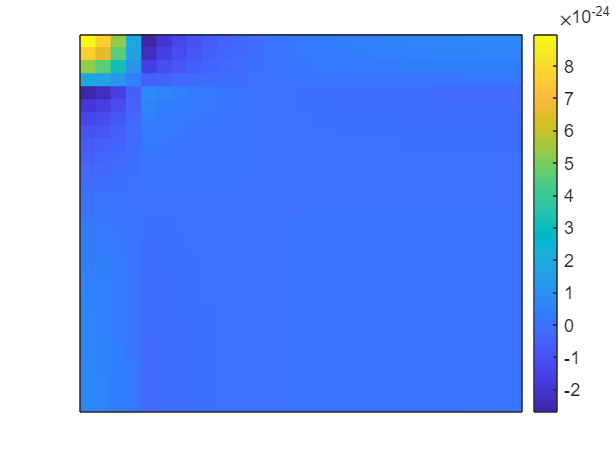

    De = (Y_GT-Y_reconstructed_1)./Y_GT;
    ErrorCov =De'*De./n;
    h = heatmap(ErrorCov);
    h.FontSize = 14;
    % original Xy label
    h.Colormap = parula;
    grid off;
    Ax = gca;
    Ax.XDisplayLabels = nan(size(Ax.XDisplayData));
    Ax.YDisplayLabels = nan(size(Ax.YDisplayData));

Permutation test

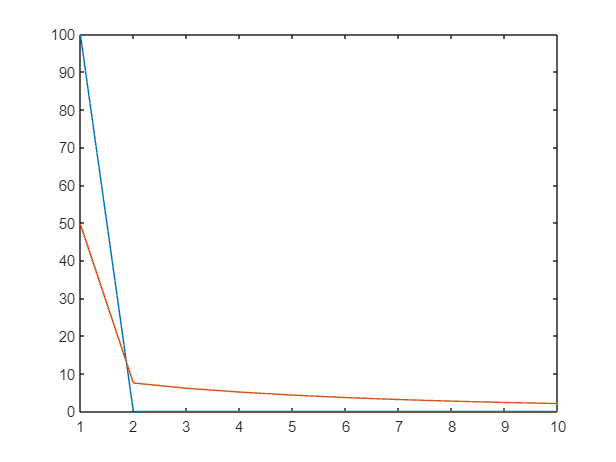

    N_permutations = 5000;
    explained_summary = zeros(size(Y_GT));
    for ii = 1:N_permutations
        for kk = 1:size(Y_GT, 1)
            Y_GT_shuffle(kk,:) = Y_GT(kk,randperm(size(Y_GT, 2)));
        end

        [coeff_temp,score_temp,latent_temp,~,explained_temp,mu_temp] = pca(Y_GT_shuffle,'Economy',false);
        explained_summary(ii,:) = explained_temp;
    end
    explained_permutation = mean(explained_summary)' ;
    
    figure();
    plot(1:10,explained_1(1:10));
    hold on;
    plot(1:10,explained_permutation(1:10));

Cross validation

    N_train = round(0.8*n);
    train_x = Y_GT(1:N_train,:);
    test_x = Y_GT(N_train +1:end,:);


%PCA analysis   
   [coeff_1,score_1,latent_1,~,explained_1,mu_1] = pca(train_x,'Economy',false);
    

%select the numbers of  PCs
    test_center = test_x -mu_1;
    test_PCA = test_center*coeff_1(:,1:N_PC);

%reconstruct the data Y_GT as Y_reconstructed_1
    Reconstruc_test = test_PCA * coeff_1(:,1:N_PC)'+ mu_1;

%plot cross validation
    figure();
    hold on;
    uq_plot([0.9*min(test_x,[],'all') 1.1*max(test_x,[],'all')], [0.9*min(test_x,[],'all') 1.1*max(test_x,[],'all')], 'k');
    axis equal;
    axis([[0.9*min(test_x,[],'all') 1.1*max(test_x,[],'all')], [0.9*min(test_x,[],'all') 1.1*max(test_x,[],'all')]]);
    uq_plot(test_x, Reconstruc_test, '+');
    xlabel('Reconstruc_train');
    ylabel('test_x');
    box on;
    hold off;
    title('test_x error');

%mse percentage error
    mseError_test = mse((test_x-Reconstruc_test)./test_x)

## Autoencoder (P X N)

Zscore the data (required)

    [Zscore_Y_GT, Zscore_mu,Zscore_std] = zscore(Y_GT);

Autoencoder ()

    Zscore_Y_GT = Zscore_Y_GT';% transpose the dimension as P X N
    autoenc = trainAutoencoder(Zscore_Y_GT);

    AE_PCs = encode(autoenc,Zscore_Y_GT)';% projection into latent reduced space
    AE_reconstruct = decode(autoenc,AE_PCs');% reconstruct
    AE_reconstruct = AE_reconstruct'.*Zscore_std + Zscore_mu;

%AE reconstruction error
    figure();
    hold on;
    
    uq_plot([0.9*min(Y_GT,[],'all') 1.1*max(Y_GT,[],'all')], [0.9*min(Y_GT,[],'all') 1.1*max(Y_GT,[],'all')], 'k');
    hold on;
    axis equal;
    axis([[0.9*min(Y_GT,[],'all') 1.1*max(Y_GT,[],'all')], [0.9*min(Y_GT,[],'all') 1.1*max(Y_GT,[],'all')]]);
    uq_plot(Y_GT, AE_reconstruct, '+');
    xlabel('Y_GT');
    ylabel('AE_reconstruct');
    box on;
    hold off;

MSE error

    mseError_2 = mse((Y_GT-AE_reconstruct)./Y_GT)

Autoencoder error covariance

    De = (Y_GT-AE_reconstruct)./Y_GT;
    ErrorCov =De'*De./n;
    h = heatmap(ErrorCov);
    h.FontSize = 15;
    % original Xy label
    h.Colormap = parula;
    grid off;
    Ax = gca;
    Ax.XDisplayLabels = nan(size(Ax.XDisplayData));
    Ax.YDisplayLabels = nan(size(Ax.YDisplayData));

Cross validation


%AE analysis  
%Zscore the data (required) and autoencoder 
    [Zscore_train, Zscore_mu_train,Zscore_std_train] = zscore(train_x);
    Zscore_train = Zscore_train';% transpose the dimension as P X N
    autoenc = trainAutoencoder(Zscore_train,100);
    
    Zscore_test = (test_x - Zscore_mu_train) ./Zscore_std_train;
    Zscore_test = Zscore_test';% transpose the dimension as P X N


%reconstruct the data  using test 

    AE_PCs = encode(autoenc,Zscore_test)';% projection into latent reduced space
    AE_reconstruct = decode(autoenc,AE_PCs');% reconstruct
    AE_reconstruct = AE_reconstruct'.*Zscore_std_train + Zscore_mu_train;


%plot cross validation
    figure();
    hold on;
    uq_plot([0.9*min(test_x,[],'all') 1.1*max(test_x,[],'all')], [0.9*min(test_x,[],'all') 1.1*max(test_x,[],'all')], 'k');
    axis equal;
    axis([[0.9*min(test_x,[],'all') 1.1*max(test_x,[],'all')], [0.9*min(test_x,[],'all') 1.1*max(test_x,[],'all')]]);
    uq_plot(test_x, AE_reconstruct, '+');
    xlabel('AE_reconstruct');
    ylabel('test_x');
    box on;
    hold off;
    title('test_x error');
%mse percentage error
    mseError_test = mse((test_x-AE_reconstruct)./test_x)